# Training a Deep Learning Network to Classify Brain Tumors using MRI images

Thang Gang Group Members: Rayan Dharia, Katie Garcia, Camryn Gerspach, Michael Olagbiyan

Course: BME3053C Computer Applications of BME

Term: Fall 2022

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

December 3rd, 2022

This program is a MATLAB live script walkthrough of the process to train a deep learning network for image recognition. In sum, a VGG-16 pretrained neural network was retrained with a datastore containing 5712 labeled images.

## Load Files to MATLAB

The images from the "Training" folder are loaded into a MATLAB datastore. The datastore is then split into two datastores, with 70% of the images being in the training datastore and 30% of the images being in the validation datastore.

imds = imageDatastore('Training','IncludeSubfolders',true,'LabelSource','foldernames');
if size(imds.Files) ~= 5712
        error("The Training Folder attempting to be accessed does not have the proper number of files. There should be 4 folders with 5,712 images total all within the Training folder. You can download the training folder at https://www.kaggle.com/datasets/masoudnickparvar/brain-tumor-mri-dataset?resource=download")
end
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);

## Load Pretrained Network

The pretrained network, VGG-16, has to be downloaded from MATLAB in order to be accessed. Each network has a required image size, which needs to be accessed and stored in a variable.

net = vgg16;
inputSize = net.Layers(1).InputSize;

## Resize and Preprocess Images

The VGG-16 network requires a specific input size and RGB images. Since some of the images are initially grayscale, all images will be converted to RGB for precaution.

augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain,"ColorPreprocessing","gray2rgb");
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation,"ColorPreprocessing","gray2rgb");

## Reset Network for Retraining

First, the trained network needs to be converted to a layer graph to access the specific layers. Then, a the function findLayersToReplace (from MATLAB, needs to be downloaded) is used to determine which layers need to be replaced. These layers are then displayed to determine what the layer is, so that it can be replaced by the same thing.

lgraph = layerGraph(net);
[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer] 

ans =   1×2 Layer array with layers:

     1   'fc8'      Fully Connected         1000 fully connected layer
     2   'output'   Classification Output   crossentropyex with 'tench' and 999 other classes

Now, replace the Fully Connected layer with a new fully connected layer

newLearnableLayer = fullyConnectedLayer(4,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

And finally, replace the classification layer.

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

## Specify Options

While most of these options are standard, the InitialLearningRate is very low. The first learning rate tested was 0.001, which produced suboptimal results, so a value of 0.0003 was used by suggestion of various sources.

options = trainingOptions('sgdm','MiniBatchSize',128,'MaxEpochs',10,'InitialLearnRate',3e-4,'Shuffle','every-epoch','ValidationData',augimdsValidation,'ValidationFrequency',50,'Verbose',false,'Plots','training-progress');

## Train the Network

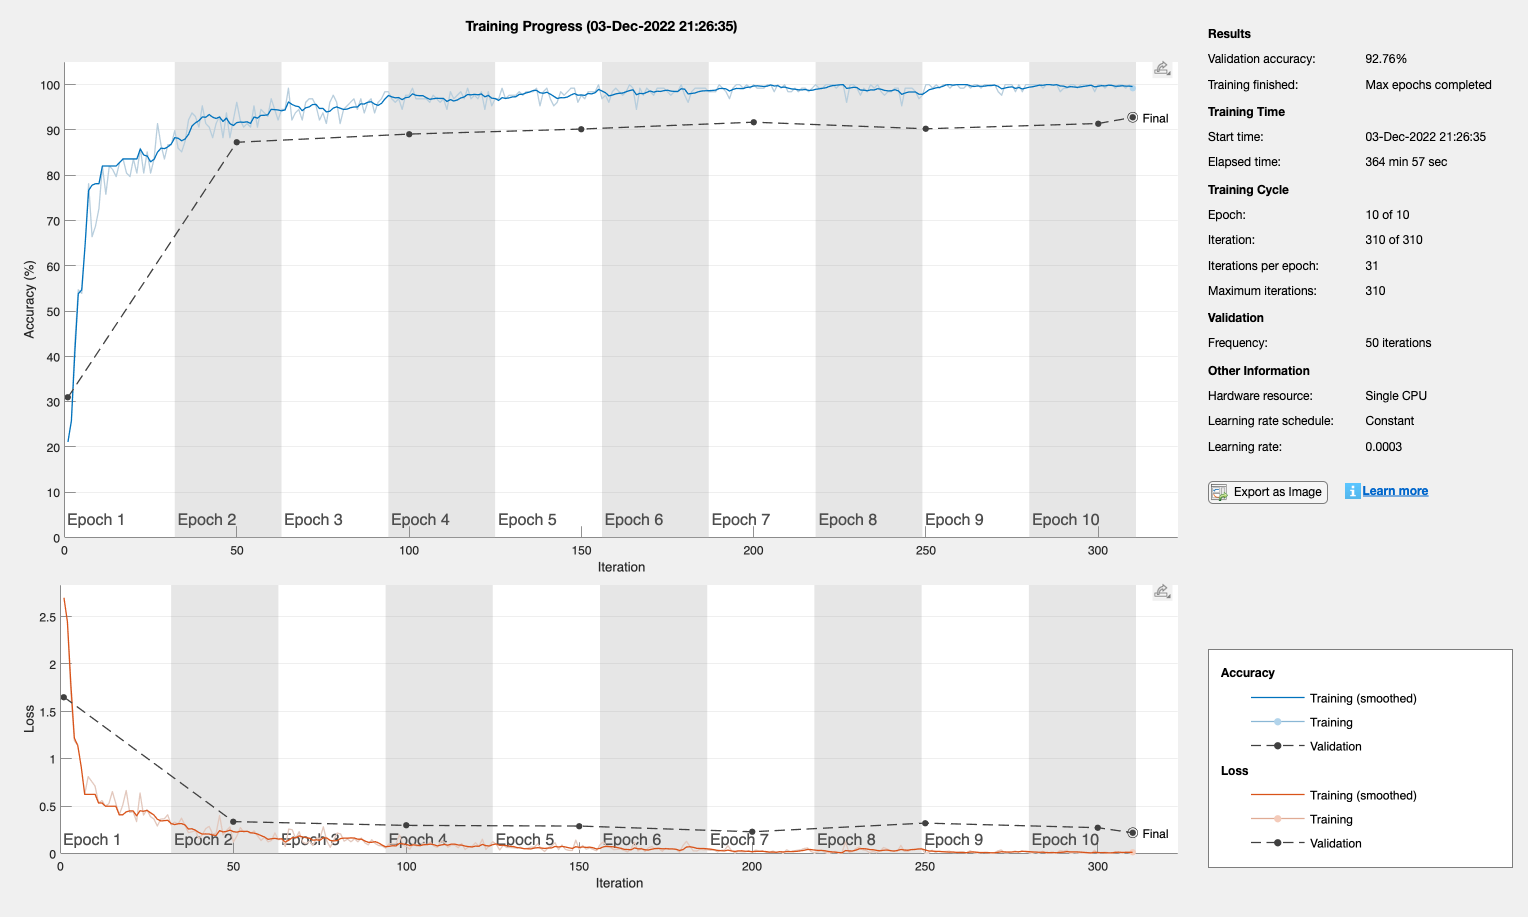

net = trainNetwork(augimdsTrain,lgraph,options);

## Determine Accuracy using Validation

Classify the validation images using the trained network and determine the accuracy

[YPred,~] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.9276